% Clear workspace to avoid "already declared" errors
clear; clc;

% 1. Define variables and boundary conditions
a = 0; 
b = pi/2; 
alpha = 0; 
beta = 1;
n = 10; % number of interior points

% 2. Define functions
p = @(x) 0; 
q = @(x) 1; 
r = @(x) 0;

% 3. Call the function
[x, y] = solve_bvp_fd(p, q, r, a, b, alpha, beta, n);

% 4. Exact solution
y_exact = sin(x);

% 5. Display table (Fixed the syntax error here)
disp('      x        Numerical      Exact');

      x        Numerical      Exact


disp([x, y, y_exact]); 

         0         0         0
    0.1428    0.1424    0.1423
    0.2856    0.2820    0.2817
    0.4284    0.4157    0.4154
    0.5712    0.5411    0.5406
    0.7140    0.6553    0.6549
    0.8568    0.7562    0.7557
    0.9996    0.8417    0.8413
    1.1424    0.9100    0.9096
    1.2852    0.9598    0.9595
    1.4280    0.9900    0.9898
    1.5708    1.0000    1.0000



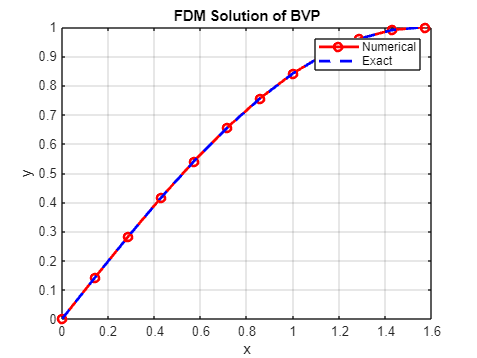


% 6. Plot
figure;
plot(x, y, 'ro-', 'LineWidth', 2); hold on;
plot(x, y_exact, 'b--', 'LineWidth', 2);
legend('Numerical', 'Exact');
xlabel('x'); ylabel('y');
title('FDM Solution of BVP');
grid on;


%% --- Function Definition ---
function [x, y] = solve_bvp_fd(p, q, r, a, b, alpha, beta, n)
    h = (b - a) / (n + 1);
    x = linspace(a, b, n + 2)'; 
    x_inner = x(2:end-1);

    A = zeros(n, n);
    B = zeros(n, 1);

    for i = 1:n
        xi = x_inner(i);
        A(i, i) = -2 + h^2 * q(xi);
        if i > 1, A(i, i-1) = 1 - (h/2) * p(xi); end
        if i < n, A(i, i+1) = 1 + (h/2) * p(xi); end
        B(i) = h^2 * r(xi);
    end

    % --- Your specific code starts here ---
    B(1) = B(1) - (1 - (h/2)*p(a+h))*alpha;
    B(end) = B(end) - (1 + (h/2)*p(b-h))*beta;

    y_inner = A\B;
    y = [alpha; y_inner; beta];
    % --- Your specific code ends here ---
end